# Problem 2-1

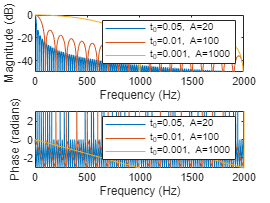

% Setting up parameters
f = 0:0.01:2000; % Small frequency spacing for sufficient resolution on case 1
t0_1 = 0.05; t0_2 = 0.01; t0_3 = 0.001;
A_1 = 20; A_2 = 100; A_3 = 1000;

% Setting up function of X(j2pif):
X = @(t0,A) A*(1-cos(2*pi.*f*t0)+1j*sin(2*pi.*f*t0))./(1j*2*pi.*f);

X_1 = X(t0_1, A_1); mag_X_1 = 20*log10(abs(X_1)); ang_X_1 = angle(X_1);
X_2 = X(t0_2, A_2); mag_X_2 = 20*log10(abs(X_2)); ang_X_2 = angle(X_2);
X_3 = X(t0_3, A_3); mag_X_3 = 20*log10(abs(X_3)); ang_X_3 = angle(X_3);

% Magnitude plots
subplot(2,1,1);
plot(f,mag_X_1,f,mag_X_2,f,mag_X_3);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
ylim([-50 0]);
legend('t_0=0.05, A=20', 't_0=0.01, A=100', 't_0=0.001, A=1000');

% Phase plots (2-1e)
subplot(2,1,2);
plot(f,ang_X_1,f,ang_X_2,f,ang_X_3);
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
legend('t_0=0.05, A=20', 't_0=0.01, A=100', 't_0=0.001, A=1000');